% Cleanup!
clear all 
close all
clc

start_trim = 53

start_trim = 53

time_length = 60

time_length = 60

[MotionData]=ParseMatlabApp('7min_nathan_50hz.mat')

MotionData = struct with fields:
            Accel: [23288×3 double]
      Orientation: [23287×3 double]
           AngVel: [23287×3 double]
          t_Accel: [23288×1 double]
    t_Orientation: [23287×1 double]
         t_AngVel: [23287×1 double]
       accel_rate: 55.5556
      orient_rate: 55.5556
      AngVel_rate: 55.5556


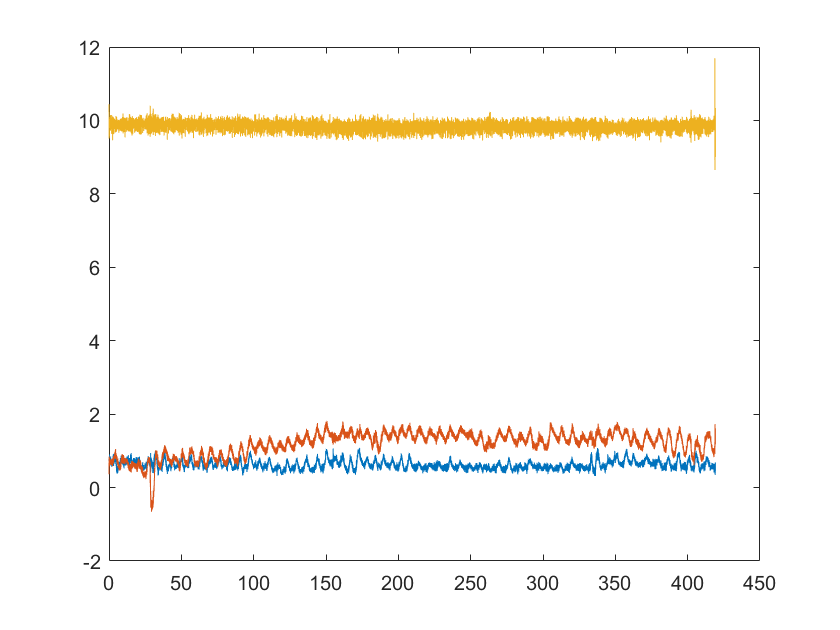

plot(MotionData.t_Accel, MotionData.Accel)

[chunked_t_Accel,chunked_Accel] = TrimMotionData(MotionData,time_length,start_trim)

Fs = 55.5556

N = 23288

chunk_sz = 60

chunks = 10

chunk_sz_index = 3333

front_trim = 53

index_front = 2945

MotionData = struct with fields:
            Accel: [23288×3 double]
      Orientation: [23287×3 double]
           AngVel: [23287×3 double]
          t_Accel: [20344×1 double]
    t_Orientation: [23287×1 double]
         t_AngVel: [23287×1 double]
       accel_rate: 55.5556
      orient_rate: 55.5556
      AngVel_rate: 55.5556



chunked_Accel =

  0×0 empty cell array


chunked_t_Accel =

  0×0 empty cell array



chunked_t_Accel = 1×21 cell array
    {3333×1 double}    {0×0 double}    {3333×1 double}    {0×0 double}    {0×0 double}    {3333×1 double}    {0×0 double}    {0×0 double}    {0×0 double}    {3333×1 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {3333×1 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {3333×1 double}


chunked_Accel = 1×21 cell array
    {3333×3 double}    {0×0 double}    {3333×3 double}    {0×0 double}    {0×0 double}    {3333×3 double}    {0×0 double}    {0×0 double}    {0×0 double}    {3333×3 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {3333×3 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {3333×3 double}


%MotionData.t_Accel = MotionData.t_Accel(index_front:index_end)-MotionData.t_Accel(1)
N = length(chunked_t_Accel{1})

N = 3333

Fs = MotionData.accel_rate % in hertz

Fs = 55.5556

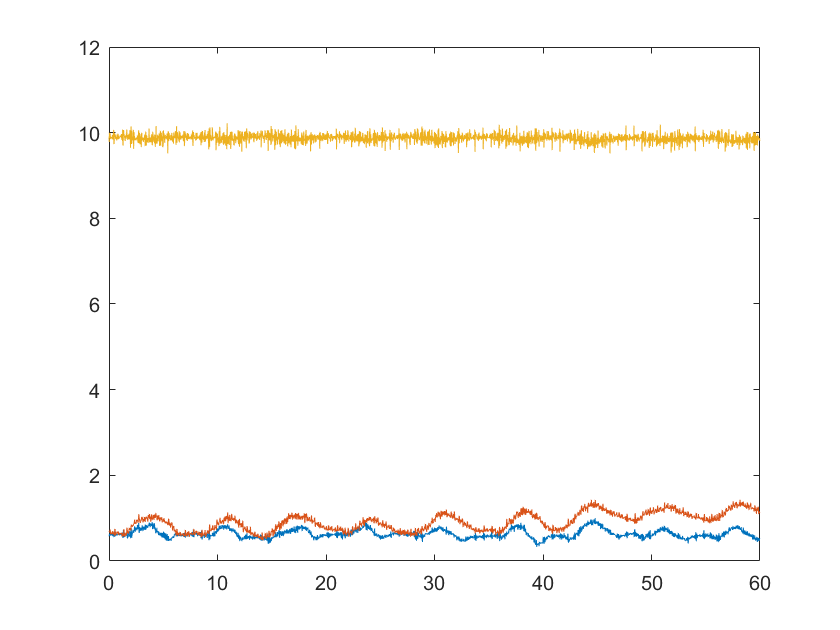

plot(chunked_t_Accel{1}, chunked_Accel{1})

%Load Control Data
[ContData]=ParseMatlabApp('10min_control_50hz.mat')

ContData = struct with fields:
            Accel: [31900×3 double]
      Orientation: [31897×3 double]
           AngVel: [31897×3 double]
          t_Accel: [31900×1 double]
    t_Orientation: [31897×1 double]
         t_AngVel: [31897×1 double]
       accel_rate: 55.5556
      orient_rate: 55.5556
      AngVel_rate: 55.5556


[chunked_t,chunked_C_Accel] = TrimMotionData(ContData,time_length,start_trim)

Fs = 55.5556

N = 31900

chunk_sz = 60

chunks = 10

chunk_sz_index = 3333

front_trim = 53

index_front = 2945

MotionData = struct with fields:
            Accel: [31900×3 double]
      Orientation: [31897×3 double]
           AngVel: [31897×3 double]
          t_Accel: [28956×1 double]
    t_Orientation: [31897×1 double]
         t_AngVel: [31897×1 double]
       accel_rate: 55.5556
      orient_rate: 55.5556
      AngVel_rate: 55.5556



chunked_Accel =

  0×0 empty cell array


chunked_t_Accel =

  0×0 empty cell array



chunked_t = 1×36 cell array
    {3333×1 double}    {0×0 double}    {3333×1 double}    {0×0 double}    {0×0 double}    {3333×1 double}    {0×0 double}    {0×0 double}    {0×0 double}    {3333×1 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {3333×1 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {3333×1 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {3333×1 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {3333×1 double}


chunked_C_Accel = 1×36 cell array
    {3333×3 double}    {0×0 double}    {3333×3 double}    {0×0 double}    {0×0 double}    {3333×3 double}    {0×0 double}    {0×0 double}    {0×0 double}    {3333×3 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {3333×3 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {3333×3 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {3333×3 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {3333×3 double}


%MotionData.t_Accel = MotionData.t_Accel(index_front:index_end)-MotionData.t_Accel(1)
N = length(chunked_t{1});
Fs = MotionData.accel_rate % in hertz

Fs = 55.5556

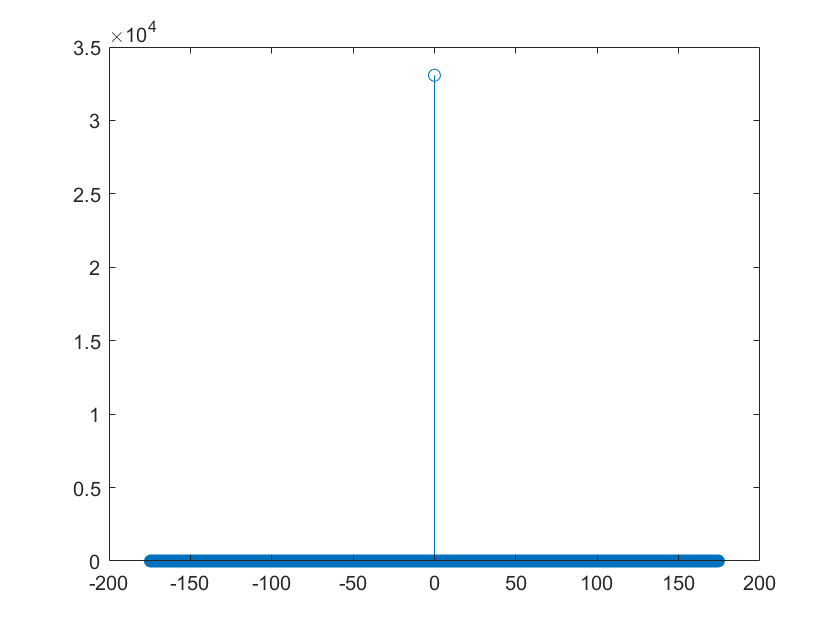

contrldata = chunked_C_Accel{1};
y_fft = fft(contrldata(:, 3));
y_fft_shift2 = abs(fftshift(y_fft));
frequencies_shifted2 = Fs*linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);
figure(1)
stem(frequencies_shifted2,y_fft_shift2)

data = chunked_Accel{1}

data =     0.5923    0.6747    9.8948
    0.5815    0.6878    9.7844
    0.6211    0.6723    9.9970
    0.6318    0.6795    9.8721
    0.6235    0.6672    9.9191
    0.5875    0.6902    9.9550
    0.6235    0.7346    9.9850
    0.6522    0.6974    9.9020
    0.6223    0.6348    9.8649
    0.6019    0.6277    9.8481


y_fft = fft(data(:, 3));
y_fft_shift = abs(fftshift(y_fft))-y_fft_shift2;
frequencies_shifted = Fs*linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);

breath_low = 8/60

breath_low = 0.1333

breath_high = 20/60

breath_high = 0.3333

hb_low = 40/60

hb_low = 0.6667

hb_high = 100/60

hb_high = 1.6667


filter_inds = breath_high <= frequencies_shifted & frequencies_shifted <= hb_low | hb_high <= frequencies_shifted | frequencies_shifted <= breath_low;
y_fft_shift(filter_inds) = y_fft_shift(filter_inds)/10;

filter_inds = find(frequencies_shifted == 0)


filter_inds =

  1×0 empty double row vector



y_fft_shift(filter_inds) = 0

y_fft_shift =     0.2482
    0.6871
    0.4072
    0.0746
    0.3759
    0.1814
    0.2322
    0.1903
    0.3246
   -0.0007


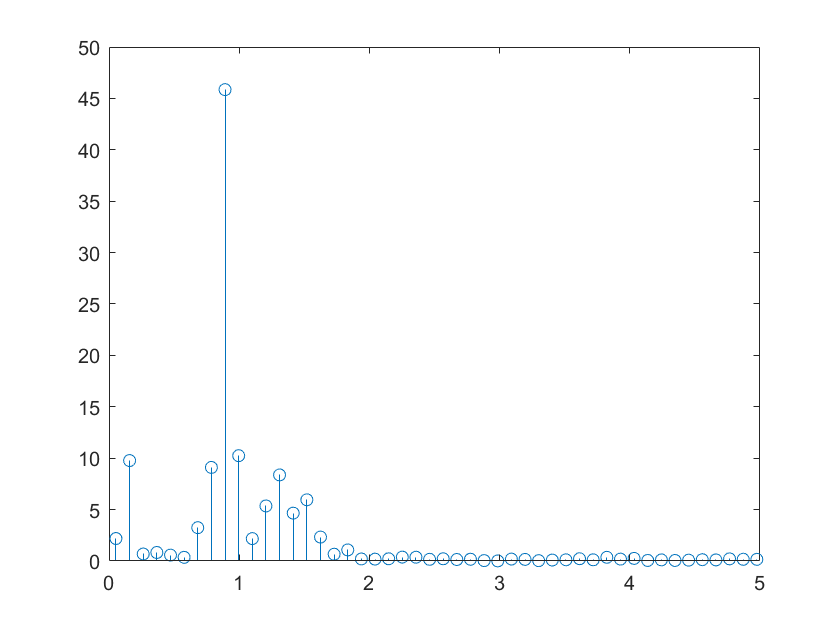


figure(2)
stem(frequencies_shifted, y_fft_shift)
xlim([0 5])